A first-order allpass filter transfer function is:


$$H(z) = \frac{a_1 + z^{-1}}{a_1+a_1z^{-1}}$$


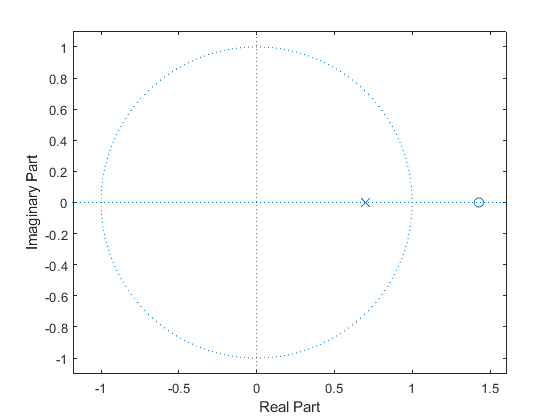

%w = pi*[0:0.001:1];  % normalized frequencies
alpha = -0.7;         % break frequency/samplerate
%tanAlpha = tan(pi*alpha);
%aap = (tanAlpha-1)/(tanAlpha+1);  
aap = [1,alpha];  % denominator
bap = [alpha,1];  % numerator
[hap,w] = freqz(bap,aap,1000);
gap = grpdelay(bap,aap,w);
zplane(bap,aap);

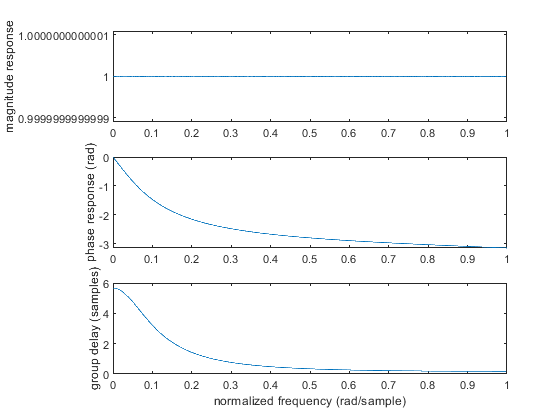

subplot(3,1,1)
plot(w/pi,abs(hap)), ylabel('magnitude response')
subplot(3,1,2)
plot(w/pi,unwrap(angle(hap))), ylabel('phase response (rad)')
subplot(3,1,3)
plot(w/pi,gap), ylabel('group delay (samples)'), xlabel('normalized frequency (rad/sample)')